## Bias-variance trade-off applied to statistical process control

The goal of this code is to illustrate the use of dimensionality reduction to control variance in a fault detection strategy. The use of Hotteling's T2 statistic is represented as fitting an ellipsoid, whereas the combined T2 and squared prediction error (SPE) is represented as a cylinder requiring fewer parameters.

*The explanation was not as successful as initially anticipated.*

clear
clf
newcolor = [55 126 184
            228 26 28
            77 175 74
            152 78 163
            255 127 0]/255

newcolor =     0.2157    0.4941    0.7216
    0.8941    0.1020    0.1098
    0.3020    0.6863    0.2902
    0.5961    0.3059    0.6392
    1.0000    0.4980         0


colororder(newcolor);

Generate random process measurements and show how an Upper- and Lower Control Limit may be used to detect outliers. In all cases, outliers (or "faults") are defined as measurements that are more than lim = 3 standard deviations away from the mean. A mean of zero is used throughout.

*This section can be improved by generating autocorrelated data*

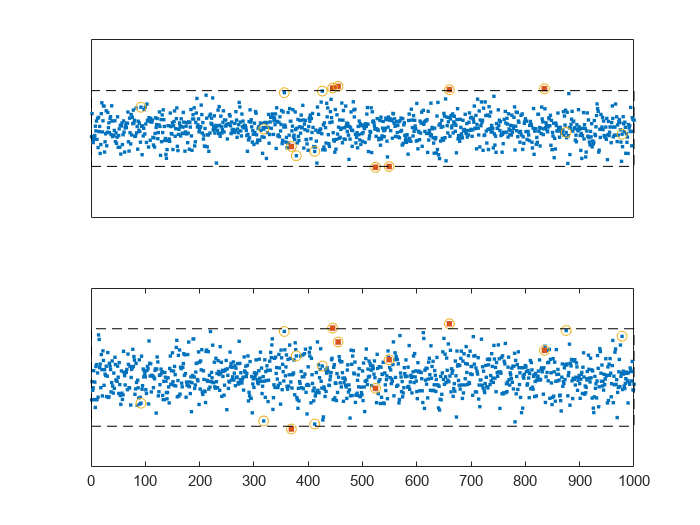

lim = 3;    % Faults are defined as falling outside of mean +- lim*std

% Generate 1000 observations from a 2D normal distribution
rng(1)
N = 1000;
mu = [0;0];
Sigma = [2, 1; 1, 3];
X = mvnrnd(mu, Sigma, N);

% Find measurements outside of the defined limits (true Faults)
Fault = find( diag(X * inv(Sigma)*X' ) > lim.^2);

% Define univariate upper and lower control limits, 
% and identify faults using univariate data
xlimit = lim*std(X(:,1));
ylimit = lim*std(X(:,2));
fault = unique([find(abs(X(:,1)) > xlimit); find(abs(X(:,2)) > ylimit)]);

% Plot time series data with LCL and UCL
figure
subplot(2,1,1)
p = plot(1:N, X(:,1),'.', ...
         fault, X(fault,1),'.',...  % Orange markers represent "detected" faults
         Fault, X(Fault,1),'o',...  % Circles represent "true" Faults
         [1 N N 1 1], xlimit*[-1 -1 1 1 -1],'k--');
a = gca(); a.YTick = []; axis([0 1000 -10 10]); a.XTick = [];
p(2).MarkerSize = 10;
subplot(2,1,2)
p = plot(1:N, X(:,2),'.', ...
         fault, X(fault,2),'.',...
         Fault, X(Fault,2),'o',...
         [1 N N 1 1], ylimit*[-1 -1 1 1 -1],'k--');
p(2).MarkerSize = 10;
a = gca(); a.YTick = []; axis([0 1000 -10 10]);

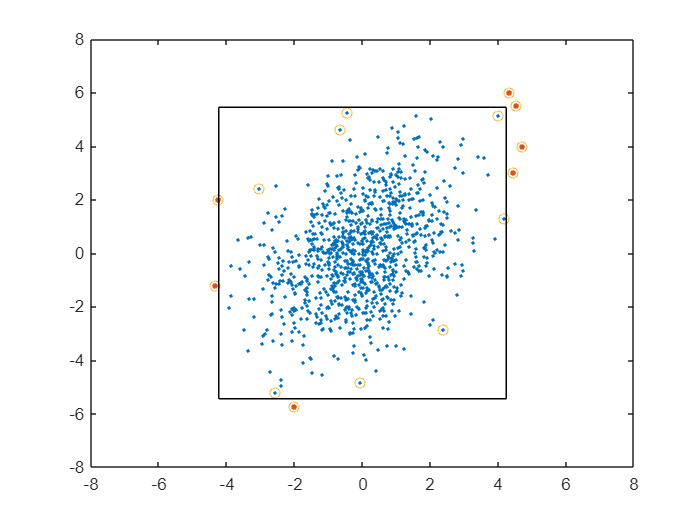


% Plot data in feature space with UCL and LCL represented by bounding box
figure
p = plot(X(:,1), X(:,2),'.', ...
     X(fault,1), X(fault,2),'.',...
     X(Fault,1), X(Fault,2),'o',...
     xlimit*[-1 -1 1 1 -1], ylimit*[-1 1 1 -1 -1], 'k');
p(2).MarkerSize = 10;
axis([-8 8 -8 8])


% Fit a normal distribution to the data, ignoring covariance, 
% and find faults
sigma = [var(X(:,1)), 0; 0, var(X(:,2))]

sigma =     1.9939         0
         0    3.2962


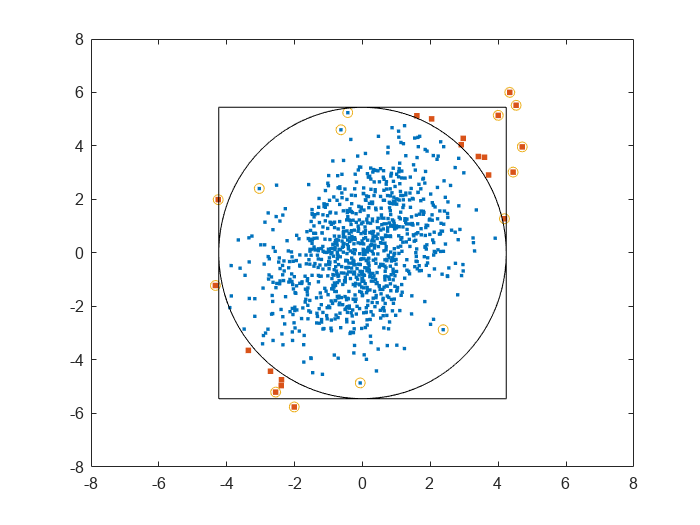

[Q, lambda] = eig(sigma);
fault = find( diag(X * inv(sigma)*X' ) > lim.^2);

% Plot the limit defined by the normal distribution
figure
t = linspace(0,2*pi);   % Parameters for circle locus
xy_circ = lim*Q*sqrt(lambda)*[cos(t); sin(t)];
p = plot(X(:,1), X(:,2),'.', ...
     X(fault,1), X(fault,2),'.',...
     X(Fault,1), X(Fault,2),'o',...
     xy_circ(1,:), xy_circ(2,:), 'k',...
     xlimit*[-1 -1 1 1 -1], ylimit*[-1 1 1 -1 -1], 'k');
p(2).MarkerSize = 10;
axis([-8 8 -8 8])

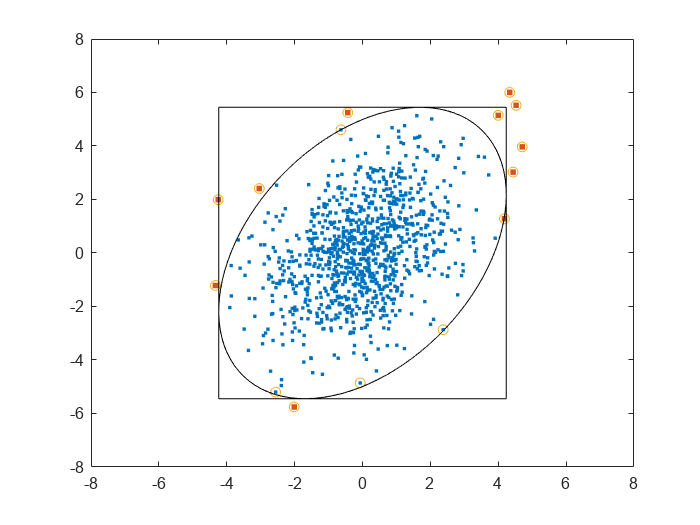


% Fit a normal distribution to the data, with covariance, 
% and find faults
sigma = cov(X);
[Q, lambda] = eig(sigma);
fault = find( diag(X * inv(sigma)*X' ) > lim.^2);

t = linspace(0,2*pi);
xy_ellips = lim*Q*sqrt(lambda)*[cos(t); sin(t)];

% Plot the limit defined by the normal distribution
figure
p = plot(X(:,1), X(:,2),'.', ...
     X(fault,1), X(fault,2),'.',...
     X(Fault,1), X(Fault,2),'o',...
     xy_ellips(1,:), xy_ellips(2,:), 'k',...
     xlimit*[-1 -1 1 1 -1], ylimit*[-1 1 1 -1 -1], 'k');
p(2).MarkerSize = 10;
axis([-8 8 -8 8])

Here, we simply illustrate the challenge of fitting an ellipse to an 8D problem, which will require 36 parameters

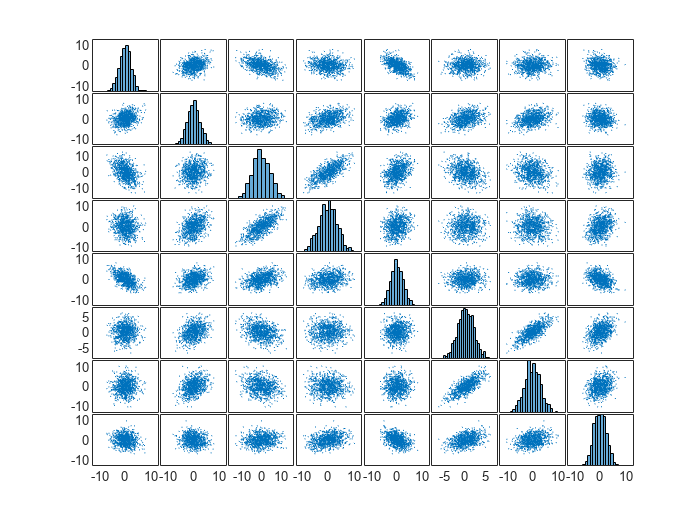

rng(1)
M = 8;
N = 1000;
mu = zeros(M,1);
Sigma = randn(M,M); Sigma = Sigma' * Sigma + diag(1*(rand(M,1)));
X = mvnrnd(mu, Sigma, N);

sigma = cov(X);
plotmatrix(X)

### Principal Component Analysis

The following section shows how PCA aims to find $q$ which maximizes the projected variance, using a 3D data set. Although $q$ is normally determined by solving the eigenvalue problem, here we use numerical optimisation in order to produce an animation showing the increase in variance as $q$ is varied.

% Generate MV normally distributed data
rng(1)
M = 3;
N = 500;
mu = zeros(M,1);
Sigma = randn(M,M); Sigma = Sigma' * Sigma + diag(5*(rand(M,1)));
[qV, Lambda] = eig(Sigma);
X = mvnrnd(mu, Sigma, N);
sigma = cov(X);

% Generate the sequence of steps during optimisation where "q" is varied to
% maximize the variance
clear global; global Y;
opts = optimset('OutputFcn', @outfun, 'MaxIter', 100, 'TolFun', 1e-5);
[~] = fminunc(@(q) -var(X*(q/norm(q))), [0; 1; 0], opts);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


% Set q1 = true optimum, due to low accuracy of optimisation method
q1 = qV(:,3);
% Store iterations + optimal vector in "Y1"
Y1 = Y; Y1(end+1,:) = Y1(end,:); Y1(end,2:4) = q1'; Y1(end,1) = Y1(end,1)+1;

% Repeat the above, this time with q2 orthogonal to q1
clear global; global Y;
opts = optimset('OutputFcn', @outfun, 'MaxIter', 100, 'TolFun', 1e-5);
[~] = fmincon(@(q) -var(  X*( (q - (q'*q1)*q1)/norm(q - (q'*q1)*q1) )  ), ...
                 [1; 0; 1], ...
                [],[],[],[],[],[], @unitcon, opts);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


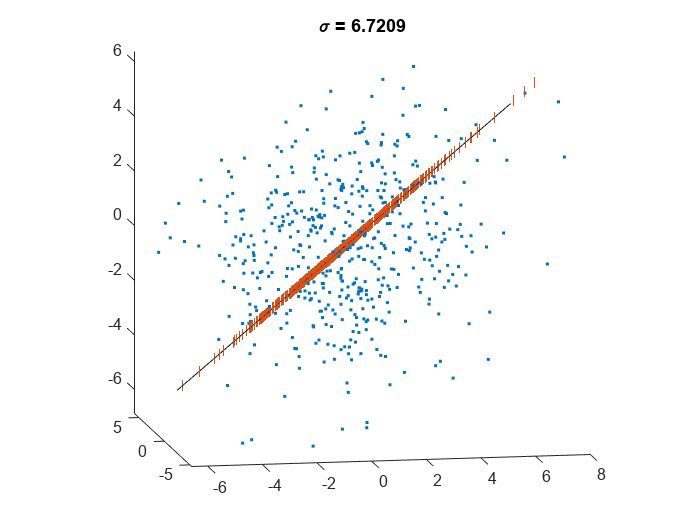

q2 = qV(:,2);
Y2 = Y; Y2(end+1,:) = Y2(end,:); Y2(end,2:4) = q2'; Y2(end,1) = Y2(end,1)+1;

% Generate a 3D plot showing the progression of the optimisation for q1
sc = 8;
figure
for i = 1:Y1(end,1)
    q = Y1(i,2:4)';     % Read current value of "q" from Y1 array
    q = q/norm(q);      % Normalize value for "q"
    T = X*q;            % Calculate the scores for current "q"

    % Plot the following
    plot3(X(:,1), X(:,2), X(:,3), '.',...   % Data in 3D
          T*q(1), T*q(2), T*q(3), '|', ...  % Scores projected onto q1
          sc*q(1)*[-1 1], sc*q(2)*[-1 1], sc*q(3)*[-1 1], 'k', ...  % q1 line
          'LineWidth', 0.5)

    view([-10.6 10.0])
    title(['\sigma = ', num2str(-Y1(i,5))]);
    axis equal
    drawnow
end

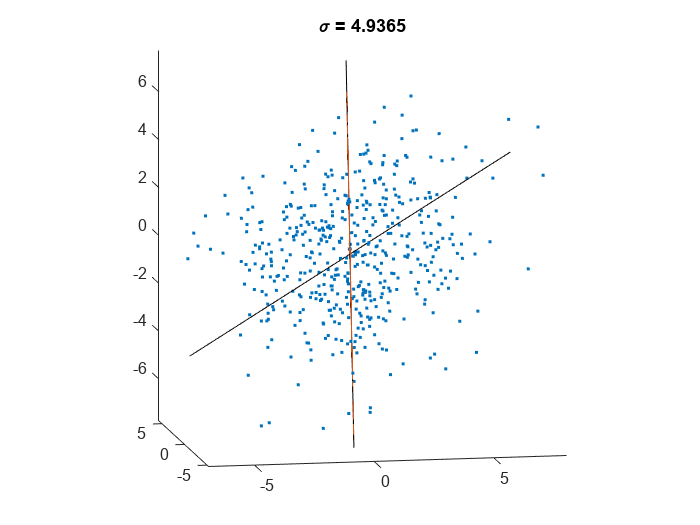


% Generate a 3D plot showing the progression of the optimisation for q2
for i = 1:Y2(end,1)
    q = Y2(i,2:4)';     % Read current value of "q" from Y1 array
    q = q/norm(q);      % Normalize value for "q"
    T = X*q;            % Calculate the scores for current "q"
    
    % Plot the following
    plot3(X(:,1), X(:,2), X(:,3), '.',...   % Data in 3D
          T*q(1), T*q(2), T*q(3), '|', ...  % Scores projected onto q2
          sc*q(1)*[-1 1], sc*q(2)*[-1 1], sc*q(3)*[-1 1], 'k', ...  % q2 line
          sc*q1(1)*[-1 1], sc*q1(2)*[-1 1], sc*q1(3)*[-1 1], 'k', ... % optimal q1 line
          'LineWidth', 0.5)

    view([-10.6 10.0])
    title(['\sigma = ', num2str(-Y2(i,5))]);
    axis equal
    drawnow
end

The code below just generates a plot showing how scores represent the data projected onto a line

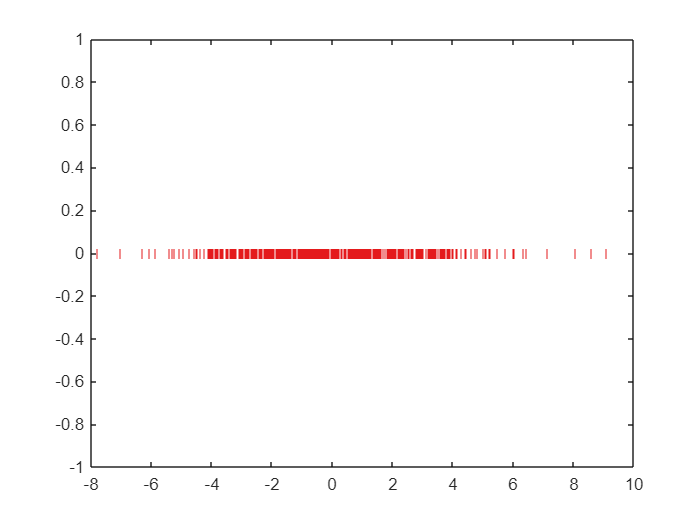

[~,T] = pca(X);
figure
plot(T(:,1), 0*T(:,1),'|','Color',newcolor(2,:))

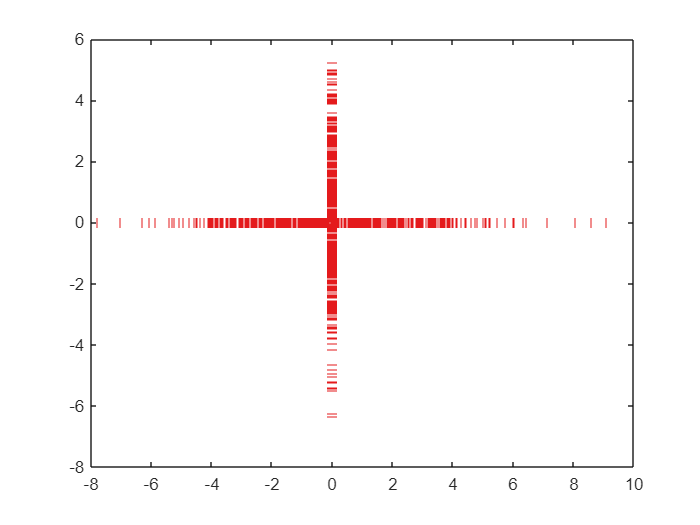


figure
plot(T(:,1), 0*T(:,1),'|',...
     0*T(:,2), T(:,2),'_',...
     'Color',newcolor(2,:))

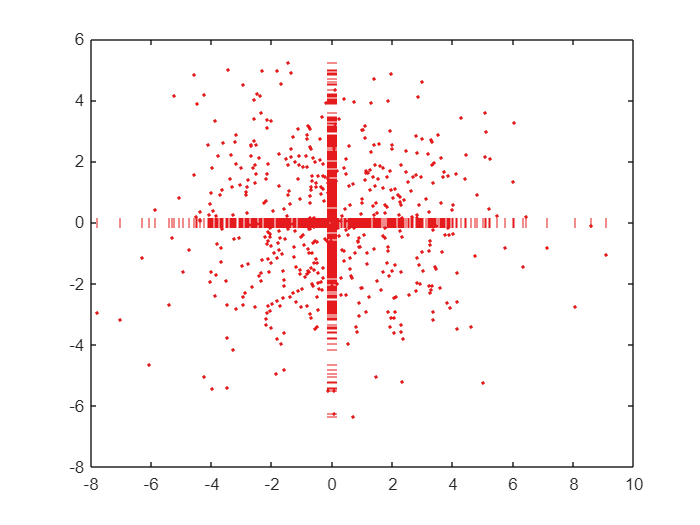


figure
plot(T(:,1), 0*T(:,1),'|',...
     0*T(:,2), T(:,2),'_',...
     T(:,1), T(:,2),'.',...
     'Color',newcolor(2,:))

The code below draws a bounding ellipse and a bounding cylinder on the 3D dataset

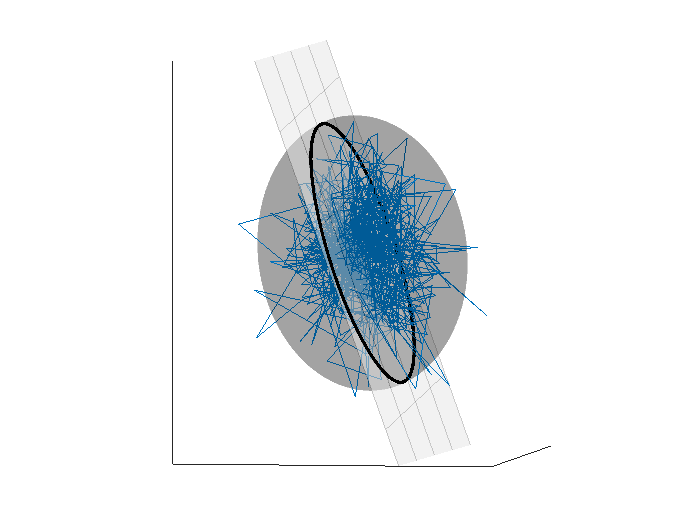

q3 = qV(:,1); % Identify 3rd principal axis of the bounding ellipse

% Plot the PC1-PC2 surface, defined using q_31*x + q_32*y q_33*z = 0
[xG, yG] = meshgrid(linspace(-8,8,5),linspace(-8,8,10));
zG = -q3(1)/q3(3)*xG - q3(2)/q3(3)*yG;

% Calculate the projected data points values
Q = [q1 q2];
T = X*Q;
X_projected = T*Q';

% Ellipse coordinates
lambda = diag([Lambda(3,3), Lambda(2,2)]);
ell = lim*(Q*sqrt(lambda)*[cos(t); sin(t)])';

% Ellipsoid coordinates, which will be calculated as an isosurface of the
% multivariate pdf
[x, y, z] = meshgrid(8*linspace(-1,1), 8*linspace(-1,1), 8*linspace(-1,1));
xyz = [x(:) y(:) z(:)];
pdf = mvnpdf(xyz, [0 0 0], sigma);
pdf = reshape(pdf, size(x));

figure
hold off
% Plot data
plot3(X(:,1), X(:,2), X(:,3),'.')
hold on

% Plot PC1-PC2 surface
s = surf(xG, yG, zG);
s.FaceColor = 0.9*[1 1 1];
s.FaceAlpha = 0.5;
s.EdgeAlpha = 0.2;

% Plot ellipse on PC surface
plot3(ell(:,1), ell(:,2), ell(:,3),'k','LineWidth',2)

% Plot ellipsoid as an isosurface at a fixed p-level
contourLevel = 0.0001;
s = isosurface(x, y, z, pdf, contourLevel);
p = patch(s);
p.LineStyle = 'none';
p.FaceAlpha = 0.2;
p.FaceColor = 'k';

axis equal
axis([-8 8 -8 8 -10 10])
a = gca(); a.XTick = []; a.YTick = []; a.ZTick = [];
view([-79.4 3.8])



% Generate standard cylinder coordinates using MATLAB built-in function
[cylx,cyly,cylz] = cylinder;
cylx = reshape(cylx, [], 1);
cyly = reshape(cyly, [], 1);
cylz = reshape(2*cylz-1, [], 1);
% Transform standard cylinder to be perpendicular to the PC1-PC2 plane
cyl = lim*(qV*sqrt(Lambda)*[cylz cyly cylx]')';
cylx = reshape(cyl(:,1), 2, []);
cyly = reshape(cyl(:,2), 2, []);
cylz = reshape(cyl(:,3), 2, []);


figure
hold off
% Plot data
plot3(X(:,1), X(:,2), X(:,3), '.');
hold on

% Plot PC1-PC2 surface
s = surf(xG, yG, zG);
s.FaceColor = 0.9*[1 1 1];
s.FaceAlpha = 0.5;
s.EdgeAlpha = 0.2;

% Plot ellipse on PC surface
plot3(ell(:,1), ell(:,2), ell(:,3),'k','LineWidth',2);

% Plot cylinder
p = surf(cylx, cyly, cylz);

p =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [2×21 double]
           YData: [2×21 double]
           ZData: [2×21 double]
           CData: [2×21 double]

  Show all properties


p.LineStyle = 'none'

p =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: 'none'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [2×21 double]
           YData: [2×21 double]
           ZData: [2×21 double]
           CData: [2×21 double]

  Show all properties


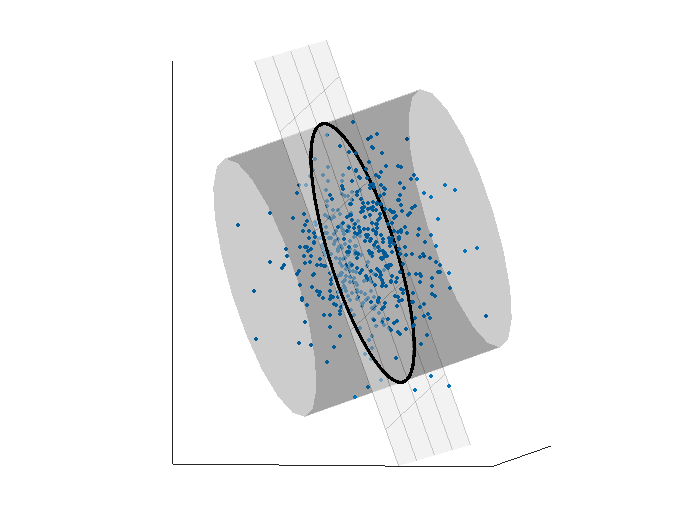

p.FaceAlpha = 0.2;
p.FaceColor = 'k';

axis equal
axis([-8 8 -8 8 -10 10])
a = gca(); a.XTick = []; a.YTick = []; a.ZTick = [];

view([-79.4 3.8])

This section simply shows the fitted ellipsoid projected in the measurement space vs the principal component space. The idea is that variations in the measurement space is significant, but variations in the principal component space are isolated to the first principal components.

*This explanation requires significant extra work.*

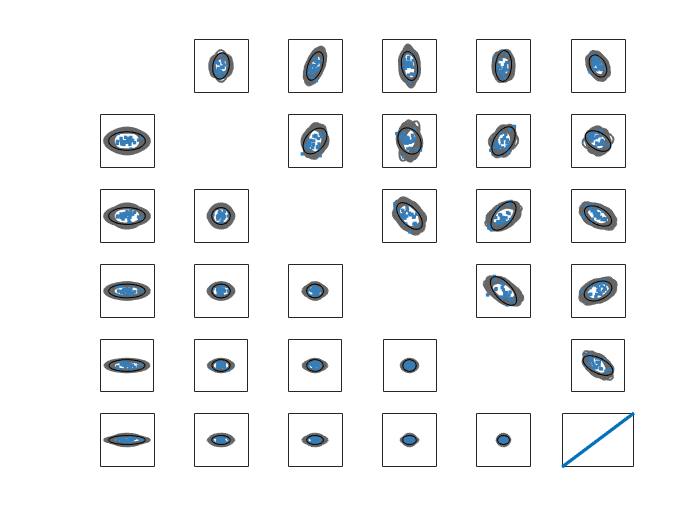

rng(1)
K = 50;     % Number of new data sets to fit training data on
M = 6;      % Number of measurements
N = 25;     % Number of data points per training set

% True MVN distribution parameters
mu = zeros(M,1);
Sigma = randn(M,M); Sigma = Sigma' * Sigma + diag(6*(rand(M,1)));

figure
sc = 15;    % sc simply defines the limits of the axes
[xG,yG] = meshgrid(sc*linspace(-1,1,50));
% `cvec` contains the matrix representing the ellips for measurements {i,j},
% with each row corresponding to a data set. 
% `evec` is the same for the PC space
for i = 1:M
    for j = 1:M
        cvec{i,j} = []; 
        evec{i,j} = [];
    end
end
for k = 1:K
    % Generate a new data set, find the covariance and PCs
    X = mvnrnd(mu, Sigma, N);
    sigma = cov(X);
    [~, T, lambda] = pca(X);

    for i = 1:M
        for j = i+1:M
            
            % Top right of matrix represents measurement space
            % Plot the ellipse by finding the constant probability contour
            % in measurement space
            pdf = reshape(...
                  mvnpdf([reshape(xG,[],1), reshape(yG,[],1)], [0, 0], sigma([i,j], [i,j])),...
                  50, 50);
            lvl = mvnpdf([lim 0], [0 0], eye(2));
            c = contourc(xG(1,:), yG(:,1), pdf, lvl*[1 1]);
            cv = c(:,2:end);
            cvec{i,j} = [cvec{i,j} cv];
            
            subplot(M,M,(i-1)*M  + j)
            p = plot(cvec{i,j}(1,:), cvec{i,j}(2,:),....
                     X(:,i), X(:,j), '.', ...
                     cv(1,:), cv(2,:), 'k', ...
                     'Color', 0.4*[1 1 1],'LineWidth',1);
            p(end-1).Color = newcolor(1,:);
            p(end).LineWidth = 0.5; p(end).Color = 'k';
            a = gca();
            a.XTick = []; a.YTick = [];
            axis square
            axis(sc*[-1 1 -1 1])


            % Bottom left of matrix represents PCA space
            % Plot the contour simply by plotting an ellipse in the PC space
            ev = lim*sqrt(diag([lambda(i), lambda(j)]))*[cos(t); sin(t)];
            evec{i,j} = [evec{i,j} ev];
            
            subplot(M,M,(j-1)*M  + i)
            p = plot(evec{i,j}(1,:), evec{i,j}(2,:), ...
                     T(:,i), T(:,j), '.', ...
                     ev(1,:), ev(2,:), 'k',....
                     'Color', 0.4*[1 1 1],'LineWidth',1);
            p(end-1).Color = newcolor(1,:);
            p(end).LineWidth = 0.5; p(end).Color = 'k';
            a = gca();
            a.XTick = []; a.YTick = [];
            axis square
            axis(1.7*sc*[-1 1 -1 1])

        end
    end
    subplot(M,M,M^2)
    plot(1:k, 1:k, 'LineWidth',2); axis([1 K 1 K]);
    a = gca();
    a.XTick = []; a.YTick = [];

    drawnow
end

This last section checks the performance of the method for fault detection using a variable number of principal components. Thresholds for T2 are still lim*std, while the SPE threshold is set arbitrarily

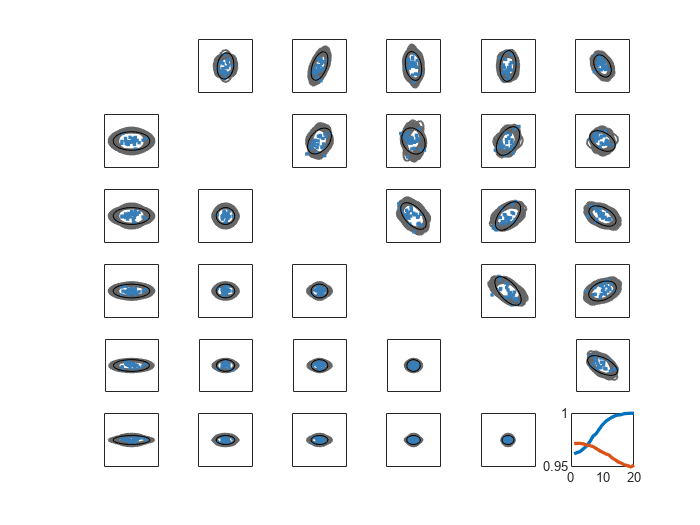

% Generate MVN data with M features and N observations
rng(1)
M = 20;
N = 100;
mu = zeros(M,1);
Sigma = randn(M,M); Sigma = Sigma' * Sigma + diag(6*(rand(M,1)));
X = mvnrnd(mu, Sigma, N);

% Determine PCs based on the observed data
sigma = cov(X);
[Q,Lambda] = eig(sigma); Lambda = diag(Lambda);

% Generate additional data sets for testing purposes, and identify the true
% Faults using the true covariance matrix
X = mvnrnd(mu, Sigma, 100*N);
Fault = ( diag(X(:,1:M-3) * inv(Sigma(1:M-3,1:M-3))*X(:,1:M-3)' ) > lim.^2);
T = X*Q;

% Cycle over different number of retained PCs
for P = 1:M
    % Exceeding T2- and Q-statistics, respectively 
    fault_T = ( diag(T(:,[1:P]) * diag(1./Lambda(1:P))*T(:,[1:P])' ) > lim.^2);
    fault_Q = (20.*sum( T(:, P+1:end).^2, 2 ) ./ sum(Lambda(P+1:end)) ) > lim.^2;
    fault = any([fault_T, fault_Q], 2);
    
    % Calculate true positive ... false negative, as well as sensitivity
    % and precision
    TP = sum(all([Fault, fault],2));
    TN = sum(all([~Fault, ~fault],2));
    FP = sum(all([~Fault, fault],2));
    FN = sum(all([Fault, ~fault],2));
    
    sens(P) = TP / (TP+FN);
    prec(P) = TP / (TP+FP);
end

% Plot the sensitivity and precision as a function of PCs
figure
plot(1:M, sens, 1:M, prec,'LineWidth',2)

% 

function stop = outfun(x,optimValues,state)
    global Y;
    stop = false;
    i=optimValues.iteration;
    Y(i+1,1)=i;
    Y(i+1,2:4)=x;
    Y(i+1,5)=optimValues.fval;
end

function [c,ceq] = unitcon(x)
    c = [];
    ceq = sum(x.^2) - 1;
end